% function [cov_matrix, ev1, ev2] = cov_analysis(raster_data, stimulus, window, fs)
% 
raster_data = P(2).raster(:,start_stim:stop_stim);
stimulus = P(2).antennal_movement(:,start_stim:stop_stim);
% raster_data = WN_Repeat_Matrix';
% stimulus = wn_stim_matrix';
window = 0.04;
% fs = 8e4;

[m,~] = size(raster_data);
STA_freq = [];
all_spike_triggers = [];
for i=1:m
    spike_locs = find(raster_data(i,:)==1);
    if isempty(spike_locs)
        continue;
    end
    for j=1:length(spike_locs)
        if (spike_locs(j)-window*fs)>= 0
            
            spike_triggers = stimulus(1,(spike_locs(j)-window*fs):spike_locs(j));
%             spike_triggers = spike_triggers-mean(spike_triggers);
            %             plot(STA); hold on;
            all_spike_triggers = [all_spike_triggers; spike_triggers];
        end
    end

end


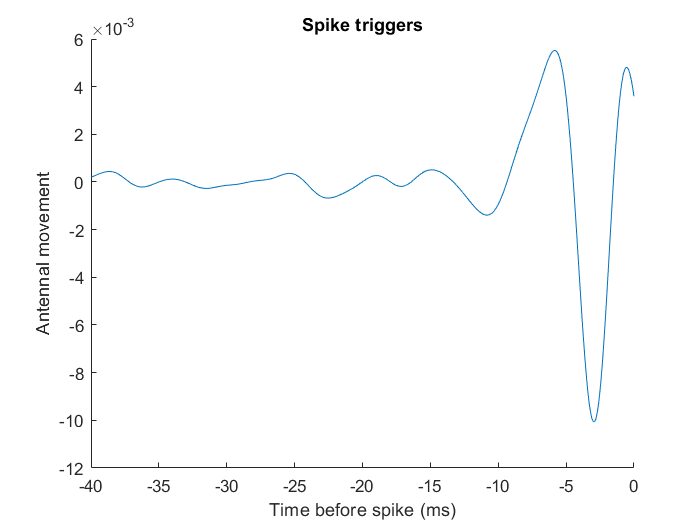


STA = mean(all_spike_triggers,1);
t= linspace(-window*1000, 0, length(STA));
figure;
plot(t, STA-mean(STA));
title('Spike Triggered Average');
% for i=1:5
%     figure;
%     plot(t, all_spike_triggers(i,:), 'k');
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end
title('Spike triggers')
xlabel('Time before spike (ms)');
ylabel('Antennal movement');
ax = gca;
ax.Box = "off";

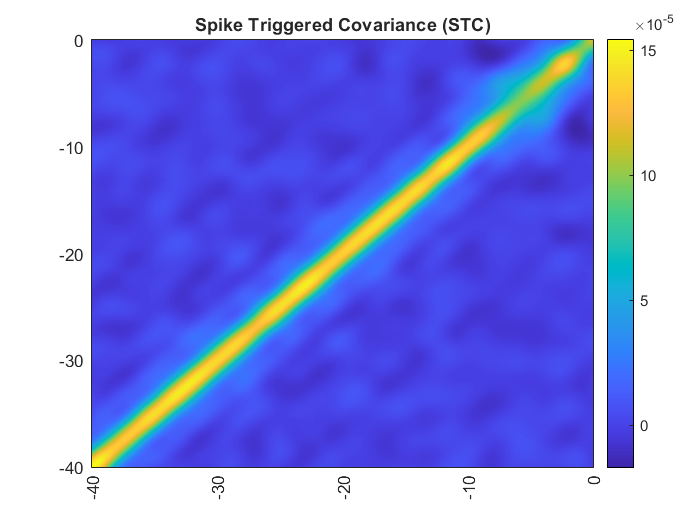


% cov_matrix = cov((all_spike_triggers-STA)');
nspikes = size(all_spike_triggers,1);
cov_matrix = (1/(nspikes -1))*(all_spike_triggers-STA)'*(all_spike_triggers-STA);
% cov_matrix = (1/(nspikes -1))*((all_spike_triggers'*all_spike_triggers)-(STA'*STA));

figure;

h = heatmap((cov_matrix), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Spike Triggered Covariance (STC)");

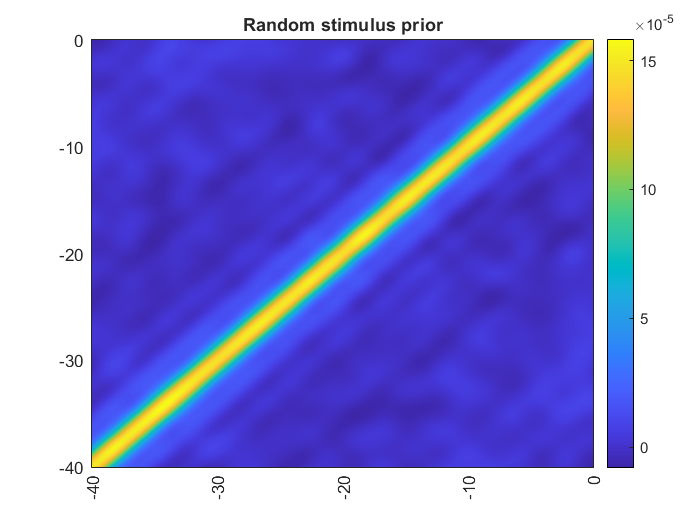

pattern_length = size(all_spike_triggers,2);
m = size(all_spike_triggers,1);
stimulus_prior = zeros([m pattern_length]);
r = randi([1 (length(stimulus)-pattern_length)],1,m);
for j=1:m
    stimulus_prior(j,:) = stimulus(randperm(size(stimulus,1),1),r(j):r(j)+pattern_length-1);
end

% for i=1:4
%     figure;
%     plot(t, stimulus_prior(i,:));
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end

% stimulus_prior = stimulus_prior(randperm(m),randperm(n));
% stimulus_prior = all_spike_triggers(randperm(m),randperm(n));
avg_stim = mean(stimulus_prior,1);
% stim_prior_cov = cov(stimulus_prior);
stim_prior_cov = (1/(m -1))*(stimulus_prior-avg_stim)'*(stimulus_prior-avg_stim);
figure;
h = heatmap((stim_prior_cov), 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("Random stimulus prior");

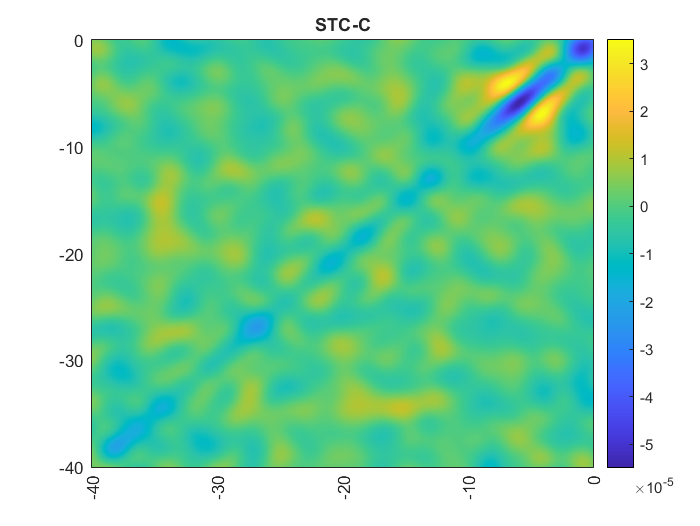

diff_cov = (cov_matrix - stim_prior_cov) ; 
figure;
h = heatmap(diff_cov, 'Colormap', parula);
h.YDisplayData = flipud(h.YDisplayData);
h.GridVisible = "off";
Labels = linspace(-window*1e3,0,length(cov_matrix));
CustomLabels = string(Labels);
CustomLabels(mod(Labels,10) ~= 0) = " ";
h.XDisplayLabels = CustomLabels;
h.YDisplayLabels = flip(CustomLabels);
title("STC-C");

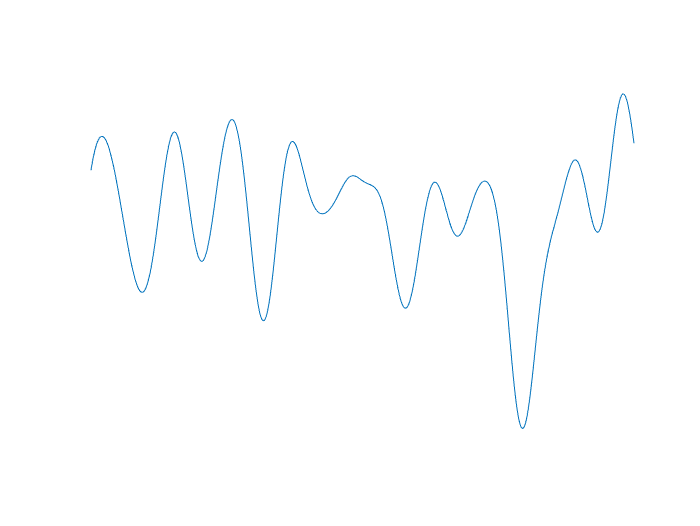

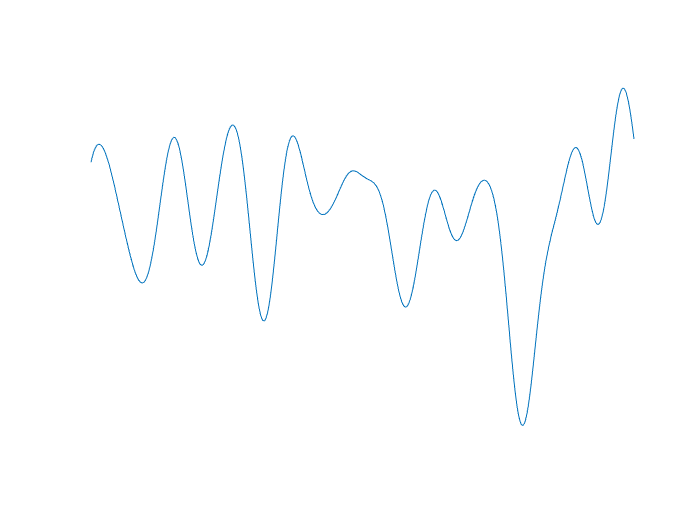

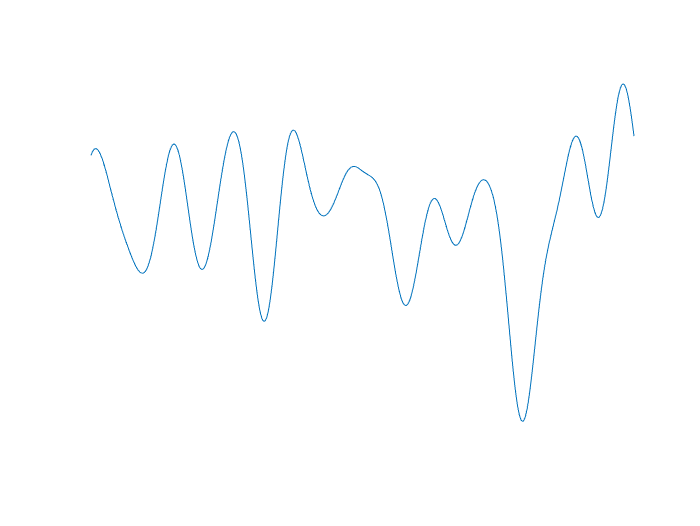


% for i=1:3
%     figure;
%     plot(t, diff_cov(i,:));
%     box off;
%     ax = gca;
%     ax.YAxis.Visible = "off";
%     ax.XAxis.Visible = "off";
%     
% end

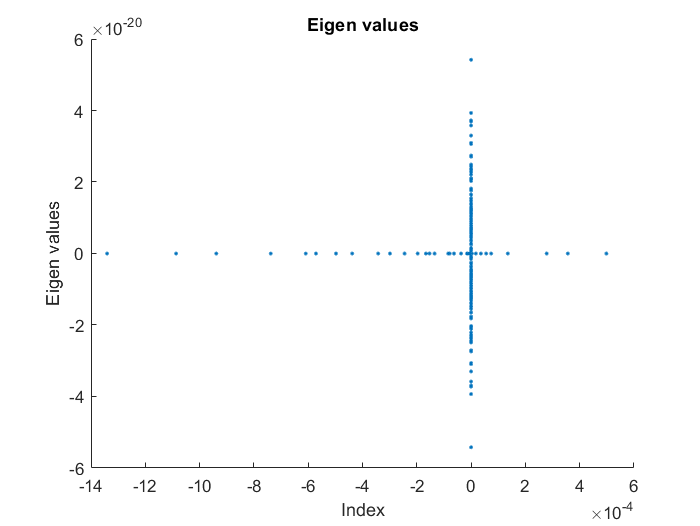


[V,D,W] = eig(diff_cov);

[~, ind] = sort(diag(D), 'descend');
Ds = D(ind,ind);
Vs = V(:,ind);
Ws = W(:,ind);

figure;
plot(diag(Ds), '.')
title('Eigen values');
ylabel('Eigen values');
xlabel('Index');
ax = gca;
ax.Box = "off";



t= linspace(-window*1000, 0, length(STA));

% figure;
% plot(t, STA-STA(1,1),t, 0.01*sum(Vs(:,1:2),2));
% title('Spike Triggered Average');
% xlabel('Time before spike (ms)');
% ylabel('Antennal movement');
% legend("STA", "Scaled sum of 2 eigen vectors", 'Location',"best")
diag_Ds = diag(Ds);
plot(t, Vs(:,1:2).*diag_Ds(1:2));

Matrix dimensions must agree.

ax = gca;
% ax.YAxis.Visible = 'off'
ax.Box = 'off';

% legend("STA","EV1","EV2");
title('Eigen vectors of STC-C');
xlabel('Time before spike (ms)');
% ylabel('Antennal movement');

% figure;
% plot(60*diff(Vs(:,2))); hold on;
% plot(Vs(:,1));



[U,S,W] = svd(diff_cov, 'econ');
D_svd = diag(S);

figure;
plot(t, W(:,1:2));
% title('Eigen vectors of diff cov by SVD');
ax = gca;
ax.YAxis.Visible = 'off'

ax =   Axes with properties:

             XLim: [-40 0]
             YLim: [-0.1500 0.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


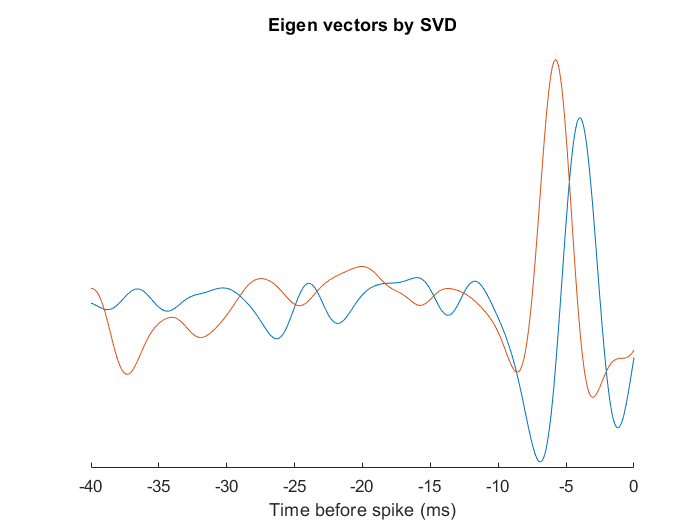

ax.Box = 'off';
xlabel('Time before spike (ms)');
title ('Eigen vectors by SVD');


% figure;
% plot(t, U(:,1).*D(1).*W(1,:)', t, U(:,2).*D(2).*W(2,:)');